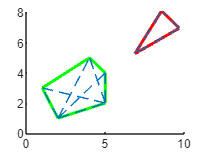

Template=[2 5 5 4 1; 1 2 4 5 3];
Image=[9.697 8.566 6.869; 6.96 8.091 5.263];
clf
nb_triangle_template=nchoosek(size(Template,2),3);
nb_triangle_image=nchoosek(size(Image,2),3);

Triangle_template=zeros(2,3*nb_triangle_template);
Index_triangle=zeros(3,nb_triangle_template);

Triangle_image=zeros(2,3*nb_triangle_image);
Index_image=zeros(3,nb_triangle_image);

triangle_template=1;

% Determination of each unique triangle
for i=1:size(Template,2)
    for j=(i+1):size(Template,2)
       
            for k=(j+1):size(Template,2)
                
                    n=0;
                    for l=1:triangle_template;
                        if n==0 && Index_triangle(1,l)==0
                            
                                Triangle_template(:,3*l-2)=Template(:,i);
                                Triangle_template(:,3*l-1)=Template(:,j);
                                Triangle_template(:,3*l)=Template(:,k);
                                Index_triangle(1,l)=i;
                                Index_triangle(2,l)=j;
                                Index_triangle(3,l)=k;
                                triangle_template=triangle_template+1;
                            
                        end
                        if i+j+k==Index_triangle(l)
                            n=1;
                        end
                    end
            end
    end
end

triangle_image=1;
for i=1:size(Image,2)
    for j=(i+1):size(Image,2)
       
            for k=(j+1):size(Image,2)
                
                    n=0;
                    for l=1:triangle_image;
                        if n==0 && Index_image(1,l)==0
                            
                                Triangle_image(:,3*l-2)=Image(:,i);
                                Triangle_image(:,3*l-1)=Image(:,j);
                                Triangle_image(:,3*l)=Image(:,k);
                                Index_image(1,l)=i;
                                Index_image(2,l)=j;
                                Index_image(3,l)=k;
                                triangle_image=triangle_image+1;
                            
                        end
                        if i+j+k==Index_image(l)
                            n=1;
                        end
                    end
            end
    end
end

Parameters=zeros(4,nb_triangle_template*nb_triangle_image);
nb_match=0;
T_template=zeros(6,nb_triangle_template);
T_image=zeros(6,nb_triangle_image);
T_matched=zeros(6,nb_triangle_template*nb_triangle_image);

% Writing the triangles from the template and the image into a usefull
% shape
for i=1:nb_triangle_template
    for j=1:nb_triangle_image
        T_template(:,i)=[Triangle_template(:,3*i-2);Triangle_template(:,3*i-1);Triangle_template(:,3*i)];
        T_image(:,j)=[Triangle_image(:,3*j-2);Triangle_image(:,3*j-1);Triangle_image(:,3*j)];
    end
end

Best_triangles=zeros(6,8);
error_mini=10000;
two_equal_errors=0;
nb_test=0;
Best_pairs=[100000 ;100000 ;100000 ;100000 ];
Best_T1=[0;0;0;0;0;0];
Best_T2=[0;0;0;0;0;0];
Best_T3=[0;0;0;0;0;0];
Best_T4=[0;0;0;0;0;0];
Best_I1=[0;0;0;0;0;0];
Best_I2=[0;0;0;0;0;0];
Best_I3=[0;0;0;0;0;0];
Best_I4=[0;0;0;0;0;0];
for i=1:nb_triangle_template
    for j=1:nb_triangle_image
        % Determination of each set of paramaters between one template
        % triangle and one image triangle
        nb_test=nb_test+1;
        Parameters(:,nb_test)=Pseudo_inverse(T_template(:,i),T_image(:,j));
        nb=0;
        
        for n=1:nb_triangle_template
            
            T_matched(:,n)=Template_to_image(T_template(:,n),Parameters(1,nb_test),Parameters(2,nb_test),Parameters(3:4,nb_test));
            Corresponding_triangle=10000;
            for m=j:nb_triangle_image
                sum=0;
                for k=1:3
                    sum=sum+(T_image(2*k,m)-T_matched(2*k,n))^2+(T_image(2*k-1,m)-T_matched(2*k-1,n))^2;
                end
                E=sqrt(sum);
                if E<Corresponding_triangle
                    Corresponding_triangle=E;
                    Best_T=T_template(:,n);
                    Best_I=T_image(:,m);
                    
                end
            end
            
            if Corresponding_triangle<Best_pairs(4) 
                test1=0;
                test2=0;
                test3=0;
                test4=0;
                test5=0;
                test6=0;
                test7=0;
                test8=0;
                test9=0;
                test10=0;
                for c=1:6
                    if Best_T1(c)~=Best_T(c) 
                        test1=test1+1;
                    end
                    if Best_T1(c)~=Best_T2(c) 
                        test9=test9+1;
                    end
                    if Best_T2(c)~=Best_T3(c) 
                        test2=test2+1;
                    end
                    if Best_T3(c)~=Best_T4(c) 
                        test3=test3+1;
                    end
                    if Best_T4(c)~=Best_T1(c) 
                        test4=test4+1;
                    end
                    if Best_I1(c)~=Best_I(c) 
                        test5=test5+1;
                    end
                    if Best_I2(c)~=Best_I3(c) 
                        test6=test6+1;
                    end
                    if Best_I3(c)~=Best_I4(c) 
                        test7=test7+1;
                    end
                    if Best_I4(c)~=Best_I1(c) 
                        test8=test8+1;
                    end
                    if Best_I1(c)~=Best_I2(c) 
                        test10=test10+1;
                    end
                end
                if (test1==6 || test5==6) || (test2==6 || test7==6) || (test3==6 || test7==6) || (test4==6 || test8==6) || (test9==6 || test10==6) 
                    Best_T4=Best_T;
                    Best_I4=Best_I;
                    Best_pairs(4)=Corresponding_triangle;
                    if Corresponding_triangle<Best_pairs(3)
                        Best_T4=Best_T3;
                        Best_I4=Best_I3;
                        Best_T3=Best_T;
                        Best_I3=Best_I;
                        Best_pairs(4)=Best_pairs(3);
                        Best_pairs(3)=Corresponding_triangle;
                        if Corresponding_triangle<Best_pairs(2)
                            Best_T4=Best_T3;
                            Best_I4=Best_I3;
                            Best_T3=Best_T2;
                            Best_I3=Best_I2;
                            Best_T2=Best_T;
                            Best_I2=Best_I;
                            Best_pairs(4)=Best_pairs(3);
                            Best_pairs(3)=Best_pairs(2);
                            Best_pairs(2)=Corresponding_triangle;
                            if Corresponding_triangle<Best_pairs(1)
                                Best_pairs(4)=Best_pairs(3);
                                Best_pairs(3)=Best_pairs(2);
                                Best_pairs(2)=Best_pairs(1);
                                Best_pairs(1)=Corresponding_triangle;

                                Best_T4=Best_T3;
                                Best_I4=Best_I3;
                                Best_T3=Best_T2;
                                Best_I3=Best_I2;
                                Best_T2=Best_T1;
                                Best_I2=Best_I1;
                                Best_T1=Best_T;
                                Best_I1=Best_I;
                                nb=nb+1;
                            end
                        end
                    end
                end                 
            end
        end
                test1=0;
                test2=0;
                test3=0;
                test4=0;
                test5=0;
                test6=0;
                test7=0;
                test8=0;
                test9=0;
                test10=0;
                for c=1:6
                    if Best_T1(c)~=Best_T(c) 
                        test1=test1+1;
                    end
                    if Best_T1(c)~=Best_T2(c) 
                        test9=test9+1;
                    end
                    if Best_T2(c)~=Best_T3(c) 
                        test2=test2+1;
                    end
                    if Best_T3(c)~=Best_T4(c) 
                        test3=test3+1;
                    end
                    if Best_T4(c)~=Best_T1(c) 
                        test4=test4+1;
                    end
                    if Best_I1(c)~=Best_I(c) 
                        test5=test5+1;
                    end
                    if Best_I2(c)~=Best_I3(c) 
                        test6=test6+1;
                    end
                    if Best_I3(c)~=Best_I4(c) 
                        test7=test7+1;
                    end
                    if Best_I4(c)~=Best_I1(c) 
                        test8=test8+1;
                    end
                    if Best_I1(c)~=Best_I2(c) 
                        test10=test10+1;
                    end
                end
        if error_mini>Best_pairs(1,1)+Best_pairs(3,1)+Best_pairs(2,1)+Best_pairs(1,1) 
            if (test1==6 || test5==6) || (test2==6 || test7==6) || (test3==6 || test7==6) || (test4==6 || test8==6) || (test9==6 || test10==6) 
                    error_mini=Best_pairs(1,1)+Best_pairs(3,1)+Best_pairs(2,1)+Best_pairs(1,1);
                    Best_triangles(:,1)=Best_T1;
                    Best_triangles(:,2)=Best_T2;
                    Best_triangles(:,3)=Best_T3;
                    Best_triangles(:,4)=Best_T4;
                    Best_triangles(:,5)=Best_I1;
                    Best_triangles(:,6)=Best_I2;
                    Best_triangles(:,7)=Best_I3;
                    Best_triangles(:,8)=Best_I4;
                    Final_parameters=Parameters(:,nb_test);
            end
         end
         if error_mini==Best_pairs(1,1)+Best_pairs(3,1)+Best_pairs(2,1)+Best_pairs(1,1)
                    two_equal_errors=1;
            
         end
    end
end

    
figure(2)                       
for i=1:size(Template,2)
    if i~=size(Template,2)
        line([Template(1,i) Template(1,i+1)],[Template(2,i) Template(2,i+1)],'Color','g','LineWidth',2);
    else
        line([Template(1,1) Template(1,i)],[Template(2,1) Template(2,i)],'Color','g','LineWidth',2);
    end
end
for i=1:size(Image,2)
    if i~=size(Image,2)
        line([Image(1,i) Image(1,i+1)],[Image(2,i) Image(2,i+1)],'Color','r','LineWidth',2);
    else
        line([Image(1,1) Image(1,i)],[Image(2,1) Image(2,i)],'Color','r','LineWidth',2);
    end
end

line([Best_I1(1) Best_I1(3)],[Best_I1(2) Best_I1(4)],'LineStyle','--')
line([Best_I1(1) Best_I1(5)],[Best_I1(2) Best_I1(6)],'LineStyle','--')
line([Best_I1(5) Best_I1(3)],[Best_I1(6) Best_I1(4)],'LineStyle','--')

line([Best_I2(1) Best_I2(3)],[Best_I2(2) Best_I2(4)],'LineStyle','--')
line([Best_I2(1) Best_I2(5)],[Best_I2(2) Best_I2(6)],'LineStyle','--')
line([Best_I2(5) Best_I2(3)],[Best_I2(6) Best_I2(4)],'LineStyle','--')

line([Best_I3(1) Best_I3(3)],[Best_I3(2) Best_I3(4)],'LineStyle','--')
line([Best_I3(1) Best_I3(5)],[Best_I3(2) Best_I3(6)],'LineStyle','--')
line([Best_I3(5) Best_I3(3)],[Best_I3(6) Best_I3(4)],'LineStyle','--')

line([Best_I4(1) Best_I4(3)],[Best_I4(2) Best_I4(4)],'LineStyle','--')
line([Best_I4(1) Best_I4(5)],[Best_I4(2) Best_I4(6)],'LineStyle','--')
line([Best_I4(5) Best_I4(3)],[Best_I4(6) Best_I4(4)],'LineStyle','--')


line([Best_T1(1) Best_T1(3)],[Best_T1(2) Best_T1(4)],'LineStyle','--')
line([Best_T1(1) Best_T1(5)],[Best_T1(2) Best_T1(6)],'LineStyle','--')
line([Best_T1(5) Best_T1(3)],[Best_T1(6) Best_T1(4)],'LineStyle','--')

line([Best_T2(1) Best_T2(3)],[Best_T2(2) Best_T2(4)],'LineStyle','--')
line([Best_T2(1) Best_T2(5)],[Best_T2(2) Best_T2(6)],'LineStyle','--')
line([Best_T2(5) Best_T2(3)],[Best_T2(6) Best_T2(4)],'LineStyle','--')

line([Best_T3(1) Best_T3(3)],[Best_T3(2) Best_T3(4)],'LineStyle','--')
line([Best_T3(1) Best_T3(5)],[Best_T3(2) Best_T3(6)],'LineStyle','--')
line([Best_T3(5) Best_T3(3)],[Best_T3(6) Best_T3(4)],'LineStyle','--')

line([Best_T4(1) Best_T4(3)],[Best_T4(2) Best_T4(4)],'LineStyle','--')
line([Best_T4(1) Best_T4(5)],[Best_T4(2) Best_T4(6)],'LineStyle','--')
line([Best_T4(5) Best_T4(3)],[Best_T4(6) Best_T4(4)],'LineStyle','--')